## COLMAP - COLMAP

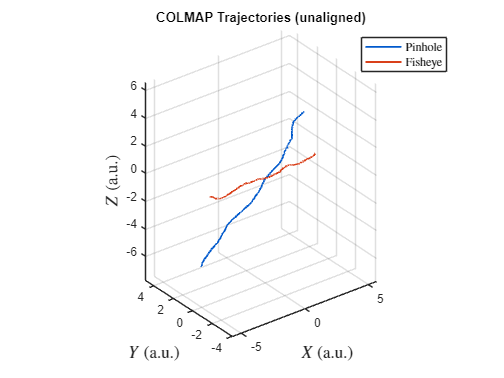

[frameid_pin, COLMAP_pin] = load_colmap('COLMAP pinhole/text/frames.txt');
[frameid_fish, COLMAP_fish] = load_colmap('COLMAP fisheye/text/frames.txt');

figure;
hold on;

plot3(COLMAP_pin(:,1), COLMAP_pin(:,2), COLMAP_pin(:,3), ...
      '-', 'Color', [0.00 0.35 0.80], 'LineWidth', 1.5);

plot3(COLMAP_fish(:,1), COLMAP_fish(:,2), COLMAP_fish(:,3), ...
      '-', 'Color', [0.85 0.25 0.10], 'LineWidth', 1.5);

legend( ...
    'Pinhole', ...
    'Fisheye', ...
    'Interpreter', 'latex', ...
    'FontSize', 10 ...
);

xlabel('$X$ (a.u.)', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$Y$ (a.u.)', 'Interpreter', 'latex', 'FontSize', 14);
zlabel('$Z$ (a.u.)', 'Interpreter', 'latex', 'FontSize', 14);

title('COLMAP Trajectories (unaligned)');

grid on;
axis equal;
view(3);
rotate3d on;

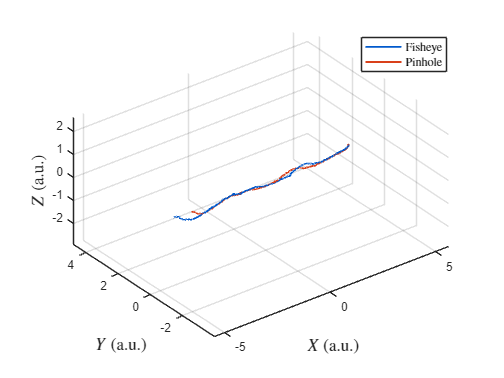

X = COLMAP_fish(:,1:3);      % Reference
Y = COLMAP_pin(:,1:3);
qX0 = COLMAP_fish(1,4:7);
qY0 = COLMAP_pin(1,4:7);


%[d, Z, transform_Y_to_X] = procrustes(X, Y);
[d, Z, transform_Y_to_X] = procrustes_fixed_position(X, Y);
%[d, Z, transform_Y_to_X] = procrustes_fixed_pose(X, Y, qX0, qY0);

figure;
hold on;
%plot3(X(:,1), X(:,2), X(:,3), 'b-', 'LineWidth', 2);
%plot3(Z(:,1), Z(:,2), Z(:,3), 'r-', 'LineWidth', 2);
plot3(X(:,1), X(:,2), X(:,3), ...
      '-', 'Color', [0.00 0.35 0.80], 'LineWidth', 1.5);
plot3(Z(:,1), Z(:,2), Z(:,3), ...
      '-', 'Color', [0.85 0.25 0.10], 'LineWidth', 1.5);

%legend('Fisheye', 'Pinhole');

legend( ...
    'Fisheye', ...
    'Pinhole', ...
    'Interpreter', 'latex', ...
    'FontSize', 10 ...
);

xlabel('$X$ (a.u.)', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$Y$ (a.u.)', 'Interpreter', 'latex', 'FontSize', 14);
zlabel('$Z$ (a.u.)', 'Interpreter', 'latex', 'FontSize', 14);
%xlabel('X (a.u.)');
%ylabel('Y (a.u.)');
%zlabel('Z (a.u.)');

%title('COLMAP Trajectories (aligned)');

grid on;
axis equal;
view(3);
rotate3d on;


err = vecnorm(X - Z, 2, 2);

rmse = sqrt(mean(err.^2));
mean_err = mean(err);
max_err = max(err);

fprintf('d: %.4f m\n', d);

d: 0.0173 m


fprintf('RMSE: %.4f m\n', rmse);

RMSE: 0.4716 m


fprintf('Mean error: %.4f m\n', mean_err);

Mean error: 0.3958 m


fprintf('Max error: %.4f m\n', max_err);

Max error: 1.0276 m


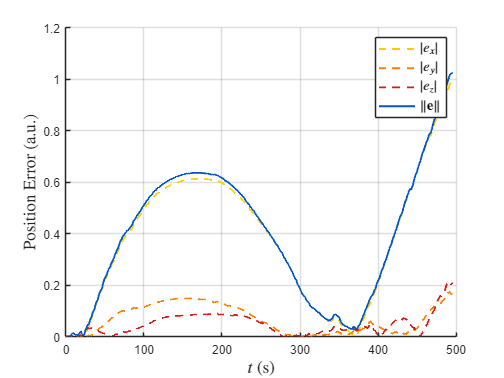

% Absolute axis-wise position errors
err_x = abs(X(:,1) - Z(:,1));
err_y = abs(X(:,2) - Z(:,2));
err_z = abs(X(:,3) - Z(:,3));

% General Euclidean error
err = vecnorm(X - Z, 2, 2);

% Time vector (3 Hz sampling)
t = (0:length(err)-1) / 3;

% Plot
figure;
hold on;

% Axis-wise errors
plot(t, err_x, '--', ...
    'Color', [1.00 0.80 0.00], ...   % yellow
    'LineWidth', 1.5);

plot(t, err_y, '--', ...
    'Color', [1.00 0.50 0.00], ...   % orange
    'LineWidth', 1.5);

plot(t, err_z, '--', ...
    'Color', [0.85 0.10 0.10], ...   % red
    'LineWidth', 1.5);

% Euclidean error
plot(t, err, 'Color', [0.00 0.35 0.80], 'LineWidth', 1.5);

xlabel('$t$ (s)', ...
    'Interpreter', 'latex', ...
    'FontSize', 14);
ylabel('Position Error (a.u.)', ...
    'Interpreter', 'latex', ...
    'FontSize', 14);

%title('Axis-wise and Total Position Error');
legend( ...
    '$|e_x|$', ...
    '$|e_y|$', ...
    '$|e_z|$', ...
    '$\|\mathbf{e}\|$', ...
    'Interpreter', 'latex', ...
    'FontSize', 12 ...
);

grid on;

R_align = transform_Y_to_X.T;

q_pin_aligned = zeros(size(COLMAP_pin(:,4:7)));

for i = 1:size(COLMAP_pin,1)

    q_pin = COLMAP_pin(i,4:7);   % [qw qx qy qz]
    R_pin = quat2rotm(q_pin);

    % Correct frame alignment
    R_pin_aligned = R_align' * R_pin;

    q_pin_aligned(i,:) = rotm2quat(R_pin_aligned);

end

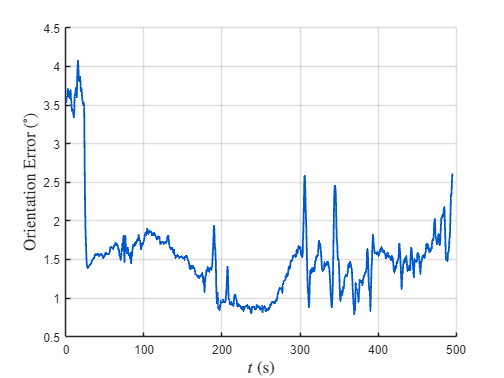

% Orientation errors (degrees)
err_ori = zeros(size(X,1),1);

for i = 1:size(X,1)

    % Reference orientation
    R_ref = quat2rotm(COLMAP_fish(i,4:7));

    % Estimated/aligned orientation
    R_est = quat2rotm(q_pin_aligned(i,:));

    % Relative rotation
    R_rel = R_ref' * R_est;

    % Geodesic angular error
    val = (trace(R_rel) - 1) / 2;
    val = max(-1, min(1, val));

    err_ori(i) = acosd(val);

end

% Time vector (3 Hz)
t = (0:length(err_ori)-1) / 3;

% Plot
figure;
hold on;

plot(t, err_ori, 'Color', [0.00 0.35 0.80], 'LineWidth', 1.5);

xlabel('$t$ (s)', ...
    'Interpreter', 'latex', ...
    'FontSize', 14);
ylabel('Orientation Error ($^\circ$)', ...
    'Interpreter', 'latex', ...
    'FontSize', 14);
%title('Orientation Error Over Time');

grid on;

## MonoSLAM - MonoSLAM

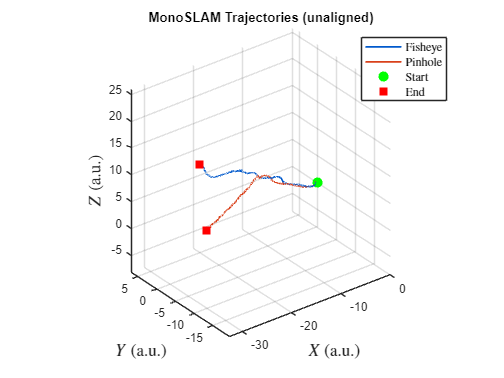

monoslam_fish = load('MonoSLAM fisheye/final/trajectory.mat').trajectory;
monoslam_pin = load('MonoSLAM pinhole/final/trajectory.mat').trajectory;

% Plot
figure;
hold on;

% Trajectories
h1 = plot3(monoslam_fish(1,:), ...
           monoslam_fish(2,:), ...
           monoslam_fish(3,:), ...
           '-', 'Color', [0.00 0.35 0.80], 'LineWidth', 1.5);

h2 = plot3(monoslam_pin(1,:), ...
           monoslam_pin(2,:), ...
           monoslam_pin(3,:), ...
           '-', 'Color', [0.85 0.25 0.10], 'LineWidth', 1.5);

% Shared start markers
h3 = plot3(monoslam_fish(1,1), monoslam_fish(2,1), monoslam_fish(3,1), ...
      'go', 'MarkerSize', 8, 'MarkerFaceColor', 'g');

plot3(monoslam_pin(1,1), monoslam_pin(2,1), monoslam_pin(3,1), ...
      'go', 'MarkerSize', 8, 'MarkerFaceColor', 'g');

% Shared end markers
h4 = plot3(monoslam_fish(1,end), monoslam_fish(2,end), monoslam_fish(3,end), ...
      'rs', 'MarkerSize', 8, 'MarkerFaceColor', 'r');

plot3(monoslam_pin(1,end), monoslam_pin(2,end), monoslam_pin(3,end), ...
      'rs', 'MarkerSize', 8, 'MarkerFaceColor', 'r');

xlabel('$X$ (a.u.)', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$Y$ (a.u.)', 'Interpreter', 'latex', 'FontSize', 14);
zlabel('$Z$ (a.u.)', 'Interpreter', 'latex', 'FontSize', 14);

title('MonoSLAM Trajectories (unaligned)');


legend([h1, h2, h3, h4], ...
    'Fisheye', ...
    'Pinhole', ...
    'Start', ...
    'End', ...
    'Interpreter', 'latex', ...
    'FontSize', 10 ...
);


%legend([h1, h2, h3, h4], ...
%       'Fisheye', 'Pinhole', 'Start', 'End');

grid on;
axis equal;
view(3);
rotate3d on;

## COLMAP - MonoSLAM

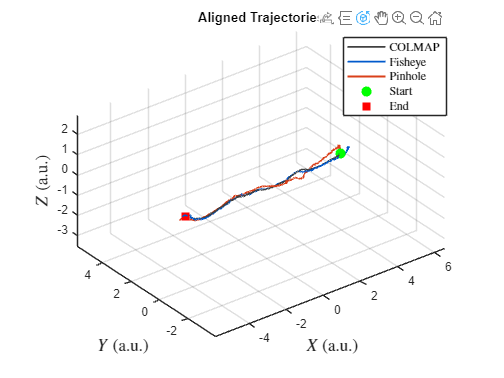

% Reference: COLMAP Fisheye
COLMAP = COLMAP_fish;
frame_id = frameid_fish;

% Match COLMAP indexes to MonoSLAM indexes
% Factor to multiply = freq_monoSLAM / freq_COLMAP
traj_idx = frame_id * 10;
%traj_idx = (frame_id - 1) * 10 + 1;

% Use same COLMAP entries
colmap_matched = COLMAP(1:end-1, :);

% Extract corresponding MonoSLAM trajectory points
monoslam_fish_matched = monoslam_fish(:, traj_idx(1:end-1))';
monoslam_pin_matched = monoslam_pin(:, traj_idx(1:end-1))';


% Procrustes: align MonoSLAM trajectories to COLMAP
[d_fisheye, monoslam_fish_aligned, transform_fisheye] = ...
    procrustes(colmap_matched(:,1:3), monoslam_fish_matched(:,1:3));

[d_pinhole, monoslam_pin_aligned, transform_pinhole] = ...
    procrustes(colmap_matched(:,1:3), monoslam_pin_matched(:,1:3));


figure;
hold on;

% COLMAP reference
h1 = plot3(colmap_matched(:,1), ...
           colmap_matched(:,2), ...
           colmap_matched(:,3), ...
           '-', 'Color', [0.25 0.25 0.25], 'LineWidth', 1.5);

% Fisheye aligned
h2 = plot3(monoslam_fish_aligned(:,1), ...
           monoslam_fish_aligned(:,2), ...
           monoslam_fish_aligned(:,3), ...
           '-', 'Color', [0.00 0.35 0.80], 'LineWidth', 1.5);

% Pinhole aligned
h3 = plot3(monoslam_pin_aligned(:,1), ...
           monoslam_pin_aligned(:,2), ...
           monoslam_pin_aligned(:,3), ...
           '-', 'Color', [0.85 0.25 0.10], 'LineWidth', 1.5);

% Shared start marker
h4 = plot3(colmap_matched(1,1), ...
           colmap_matched(1,2), ...
           colmap_matched(1,3), ...
           'go', 'MarkerSize', 8, 'MarkerFaceColor', 'g');

% Shared end marker
h5 = plot3(colmap_matched(end,1), ...
           colmap_matched(end,2), ...
           colmap_matched(end,3), ...
           'rs', 'MarkerSize', 8, 'MarkerFaceColor', 'r');

xlabel('$X$ (a.u.)', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$Y$ (a.u.)', 'Interpreter', 'latex', 'FontSize', 14);
zlabel('$Z$ (a.u.)', 'Interpreter', 'latex', 'FontSize', 14);

title('Aligned Trajectories');

%legend([h1, h2, h3, h4, h5], ...
%       'COLMAP', 'Fisheye', 'Pinhole', 'Start', 'End');

legend( ...
    'COLMAP', 'Fisheye', 'Pinhole', 'Start', 'End', ...
    'Interpreter', 'latex', ...
    'FontSize', 10 ...
);

grid on;
axis equal;
view(3);
rotate3d on;

% Errors per matched frame
err_fisheye = vecnorm(colmap_matched(:,1:3) - monoslam_fish_aligned, 2, 2);
err_pinhole = vecnorm(colmap_matched(:,1:3) - monoslam_pin_aligned, 2, 2);

% Summary metrics
rmse_fisheye = sqrt(mean(err_fisheye.^2));
rmse_pinhole = sqrt(mean(err_pinhole.^2));

mean_fisheye = mean(err_fisheye);
mean_pinhole = mean(err_pinhole);

median_fisheye = median(err_fisheye);
median_pinhole = median(err_pinhole);

max_fisheye = max(err_fisheye);
max_pinhole = max(err_pinhole);

fprintf('Fisheye RMSE: %.4f m\n', rmse_fisheye);

Fisheye RMSE: 0.2711 m


fprintf('Pinhole RMSE: %.4f m\n', rmse_pinhole);

Pinhole RMSE: 0.8295 m



fprintf('Fisheye mean error: %.4f m\n', mean_fisheye);

Fisheye mean error: 0.2240 m


fprintf('Pinhole mean error: %.4f m\n', mean_pinhole);

Pinhole mean error: 0.7681 m


fprintf('Fisheye max error: %.4f m\n', max_fisheye);

Fisheye max error: 0.5987 m


fprintf('Pinhole max error: %.4f m\n', max_pinhole);

Pinhole max error: 1.5688 m


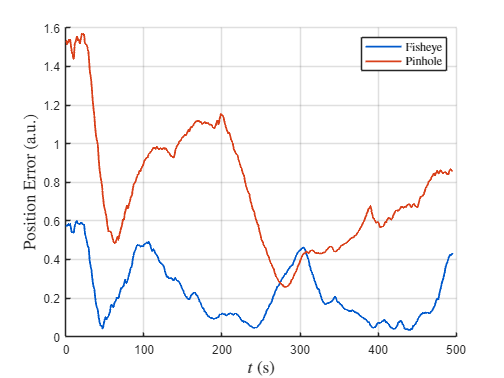

% Time vector (3 Hz)
t = (0:length(colmap_matched)-1) / 3;

figure;
hold on;

plot(t, err_fisheye, '-', 'Color', [0.00 0.35 0.80], 'LineWidth', 1.5);
plot(t, err_pinhole, '-', 'Color', [0.85 0.25 0.10], 'LineWidth', 1.5);

xlabel('$t$ (s)', ...
    'Interpreter', 'latex', ...
    'FontSize', 14);
ylabel('Position Error (a.u.)', ...
    'Interpreter', 'latex', ...
    'FontSize', 14);
%title('Trajectory Alignment Error');


legend( ...
    'Fisheye', ...
    'Pinhole', ...
    'Interpreter', 'latex', ...
    'FontSize', 10 ...
);

grid on;

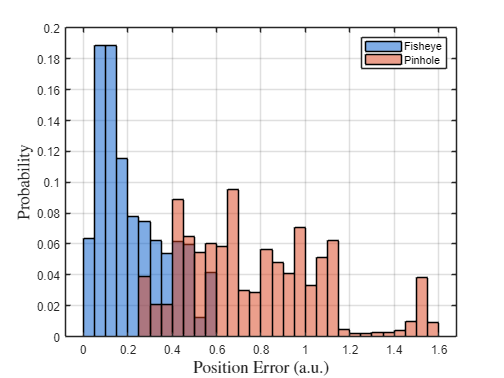

figure;
histogram(err_fisheye, 'BinWidth',0.05, ...
         'Normalization', 'probability', ...
          'FaceColor', [0.00 0.35 0.80], ...
          'FaceAlpha', 0.5);

hold on;

histogram(err_pinhole, 'BinWidth',0.05, ...
         'Normalization', 'probability', ...
          'FaceColor', [0.85 0.25 0.10], ...
          'FaceAlpha', 0.5);

xlabel('Position Error (a.u.)', ...
    'Interpreter', 'latex', ...
    'FontSize', 14);
ylabel('Probability', ...
    'Interpreter', 'latex', ...
    'FontSize', 14);


legend('Fisheye','Pinhole');
grid on;

R_align_fish = transform_fisheye.T;
R_align_pin = transform_pinhole.T;

q_fish_aligned = zeros(size(colmap_matched(:,4:7)));
q_pin_aligned = zeros(size(colmap_matched(:,4:7)));

for i = 1:size(colmap_matched,1)
    
    % Fish
    q_fish = monoslam_fish_matched(i,4:7);   % [qw qx qy qz]
    R_fish = quat2rotm(q_fish);
    R_fish_aligned = R_align_fish' * R_fish;
    q_fish_aligned(i,:) = rotm2quat(R_fish_aligned);

    % Pin
    q_pin = monoslam_pin_matched(i,4:7);     % [qw qx qy qz]
    R_pin = quat2rotm(q_pin);
    R_pin_aligned = R_align_pin' * R_pin;
    q_pin_aligned(i,:) = rotm2quat(R_pin_aligned);

end

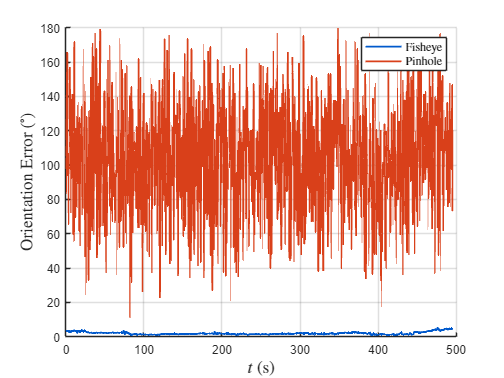

% Orientation errors (degrees)
err_ori_fish = zeros(size(colmap_matched,1),1);
err_ori_pin = zeros(size(colmap_matched,1),1);

for i = 1:size(colmap_matched,1)

    % Reference orientation
    R_ref = quat2rotm(colmap_matched(i,4:7));

    % Estimated/aligned orientations
    R_est_fish = quat2rotm(q_fish_aligned(i,:));
    R_est_pin = quat2rotm(q_pin_aligned(i,:));


    % Relative rotations
    R_rel_fish = R_ref' * R_est_fish;
    R_rel_pin = R_ref' * R_est_pin;

    % Geodesic angular error
    val = (trace(R_rel_fish) - 1) / 2;
    val = max(-1, min(1, val));
    err_ori_fish(i) = acosd(val);

    val = (trace(R_rel_pin) - 1) / 2;
    val = max(-1, min(1, val));
    err_ori_pin(i) = acosd(val);

end

% Time vector (3 Hz)
t = (0:length(colmap_matched)-1) / 3;

% Plot
figure;
hold on;

plot(t, err_ori_fish, '-', 'Color', [0.00 0.35 0.80], 'LineWidth', 1.5);
plot(t, err_ori_pin, '-', 'Color', [0.85 0.25 0.10], 'LineWidth', 1.5);

legend( ...
    'Fisheye', ...
    'Pinhole', ...
    'Interpreter', 'latex', ...
    'FontSize', 10 ...
);

xlabel('$t$ (s)', ...
    'Interpreter', 'latex', ...
    'FontSize', 14);
ylabel('Orientation Error ($^\circ$)', ...
    'Interpreter', 'latex', ...
    'FontSize', 14);
%title('Orientation Error Over Time');

grid on;

function [frame_id, COLMAP] = load_colmap(filename)

    fid = fopen(filename, 'r');
    
    data = textscan(fid, ...
        '%f %f %f %f %f %f %f %f %f %*[^\n]', ...
        'CommentStyle', '#');
    
    fclose(fid);
    
    frame_id = data{1};
    
    QW = data{3};
    QX = data{4};
    QY = data{5};
    QZ = data{6};
    
    TX = data{7};
    TY = data{8};
    TZ = data{9};
    
    % [X Y Z QW QX QY QZ]
    COLMAP = zeros(length(frame_id), 7);
    
    for i = 1:length(frame_id)
    
        q_cw = [QW(i), QX(i), QY(i), QZ(i)];
        t_cw = [TX(i); TY(i); TZ(i)];
    
        R_cw = quat2rotm(q_cw);
    
        % Camera center in world coordinates
        C_w = -R_cw' * t_cw;
    
        % Camera orientation in world coordinates
        q_wc = [q_cw(1), -q_cw(2), -q_cw(3), -q_cw(4)];
    
        % Store [position quaternion]
        COLMAP(i,:) = [C_w' q_wc];
    
    end
end


function [d, Z, transform] = procrustes_fixed_position(X, Y)

    % X = reference, N x 3
    % Y = trajectory to align, N x 3

    % Force both trajectories to start from zero
    X0 = X - X(1,:);
    Y0 = Y - Y(1,:);

    % Estimate rotation with fixed origin
    H = X0' * Y0;
    [U, ~, V] = svd(H);

    T = V * U';

    % Avoid reflection
    if det(T) < 0
        V(:,end) = -V(:,end);
        T = V * U';
    end

    % Estimate scale
    b = trace((Y0 * T)' * X0) / trace(Y0' * Y0);

    % Fixed translation: make first points match exactly
    c = X(1,:) - b * Y(1,:) * T;

    % Apply transform
    Z = b * Y * T + c;

    % MATLAB-style normalization
    X_centered = X - mean(X,1);
    d = sum(vecnorm(X - Z, 2, 2).^2) / ...
        sum(vecnorm(X_centered, 2, 2).^2);

    % Store transform
    transform.T = T;
    transform.b = b;
    transform.c = repmat(c, size(Y,1), 1);
end

function [d, Z, transform] = procrustes_fixed_pose(X, Y, qX0, qY0)

    X0 = X - X(1,:);
    Y0 = Y - Y(1,:);

    R0_X = quat2rotm(qX0);   % reference orientation
    R0_Y = quat2rotm(qY0);   % source orientation

    % Correct fixed rotation for row-vector position transform Y*T
    T = R0_Y * R0_X';

    % Estimate scale only
    b = trace((Y0 * T)' * X0) / trace(Y0' * Y0);

    % Force initial positions to match
    c = X(1,:) - b * Y(1,:) * T;

    % Apply transform
    Z = b * Y * T + c;

    % MATLAB-style normalized disparity
    X_centered = X - mean(X,1);

    d = sum(vecnorm(X - Z, 2, 2).^2) / ...
        sum(vecnorm(X_centered, 2, 2).^2);

    transform.T = T;
    transform.b = b;
    transform.c = repmat(c, size(Y,1), 1);

end